# 1. MATLABにおける配列の基本操作

## ツールボックスのインストールとパスの設定

toolbox_signal と toolbox_general の2つのファイルをダウンロードする．

これらのツールボックスを作業用ディレクトリ※に解凍して，以下を実行してパスを通す．

※ 作業用ディレクトリ：MATLABメイン画面で変更可能．

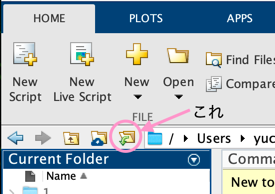

MATLABのライブスクリプトでの実行方法．

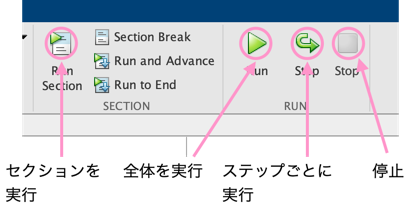

a = rand(1);
who


変数:

a  



whos a

  Name      Size            Bytes  Class     Attributes

  a         1x1                 8  double              



clear; % すべての変数をクリア
clf; % すべてのウィンドウを閉じる
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');

乱数発生機の初期化（固定）．

rng('default');

MATLABに標準的に実装されている関数の説明を help コマンドで表示できる．ライブスクリプトだと右ウインドウに表示される．

help size % size関数の説明

 size   Size of array.  
    D = size(X), for M-by-N matrix X, returns the two-element row vector
    D = [M,N] containing the number of rows and columns in the matrix.
    For N-D arrays, size(X) returns a 1-by-N vector of dimension lengths.
    Trailing singleton dimensions are ignored.
 
    [M,N] = size(X) for matrix X, returns the number of rows and columns in
    X as separate output variables. 
    
    [M1,M2,M3,...,MN] = size(X) for N>1 returns the sizes of the first N 
    dimensions of the array X.  If the number of output arguments N does
    not equal NDIMS(X), then for:
 
    N > NDIMS(X), size returns ones in the "extra" variables, i.e., outputs
                  NDIMS(X)+1 through N.
    N < NDIMS(X), MN contains the product of the sizes of dimensions N
                  through NDIMS(X).
 
    M = size(X,DIM) returns the lengths of the specified dimens

コメントは%を用いる．

% これはコメントです

## 基本的な配列操作

変数や配列の定義．

※コマンドの最後のセミコロンを省くと実行結果がそのまま表示される．

a = 1 % 実数

a = 1

a = 2+1i % 複素数

a = 2.0000 + 1.0000i

b = [1 2 3 4] % 行ベクトル

b =      1     2     3     4


c = [1; 2; 3; 4] % 列ベクトル

c =      1
     2
     3
     4


コロン演算子を用いることで連続した数値からなる配列を生成できる．

d = 1:4 % d=[1 2 3 4]

d =      1     2     3     4


d = 1:2:7 % d=[1 3 5 7]

d =      1     3     5     7


配列の1つのエントリにアクセスしたり，インデックスを付けてサブ配列を選択できたりする．

size(d) % 配列のサイズ

ans =      1     4


d(1) % 配列の1番目の要素（MATLAB/Octave のインデックスは1から始まることに注意）

ans = 1

d(1:2) % 配列の1,2番目の要素からなるサブ配列

ans =      1     3


d([1,3,4]) % 配列の1,3,4番目の要素からなるサブ配列

ans =      1     5     7


標準的な関数を用いることで様々な配列を作成できる．

A = eye(4,4) % 4x4の単位行列

A =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


B = ones(4,4) % 4x4のオール1行列

B =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


C = rand(4,4) % 4x4の区間[0,1]で一様分布する実数からなるランダム行列

C =     0.8147    0.6324    0.9575    0.9572
    0.9058    0.0975    0.9649    0.4854
    0.1270    0.2785    0.1576    0.8003
    0.9134    0.5469    0.9706    0.1419


Ct = C.' % 行列Cの転置

Ct =     0.8147    0.9058    0.1270    0.9134
    0.6324    0.0975    0.2785    0.5469
    0.9575    0.9649    0.1576    0.9706
    0.9572    0.4854    0.8003    0.1419


B2 = B + i * C; % 複素行列
B2' % 行列B2の複素共役転置

ans =    1.0000 - 0.8147i   1.0000 - 0.9058i   1.0000 - 0.1270i   1.0000 - 0.9134i
   1.0000 - 0.6324i   1.0000 - 0.0975i   1.0000 - 0.2785i   1.0000 - 0.5469i
   1.0000 - 0.9575i   1.0000 - 0.9649i   1.0000 - 0.1576i   1.0000 - 0.9706i
   1.0000 - 0.9572i   1.0000 - 0.4854i   1.0000 - 0.8003i   1.0000 - 0.1419i


B2.' % 行列B2の転置（共役にしない）

ans =    1.0000 + 0.8147i   1.0000 + 0.9058i   1.0000 + 0.1270i   1.0000 + 0.9134i
   1.0000 + 0.6324i   1.0000 + 0.0975i   1.0000 + 0.2785i   1.0000 + 0.5469i
   1.0000 + 0.9575i   1.0000 + 0.9649i   1.0000 + 0.1576i   1.0000 + 0.9706i
   1.0000 + 0.9572i   1.0000 + 0.4854i   1.0000 + 0.8003i   1.0000 + 0.1419i


C2 = rand(4, 4, 4) % 4x4x4のテンソル（3次元配列）

C2 = C2(:,:,1) =

    0.4218    0.6557    0.6787    0.6555
    0.9157    0.0357    0.7577    0.1712
    0.7922    0.8491    0.7431    0.7060
    0.9595    0.9340    0.3922    0.0318


C2(:,:,2) =

    0.2769    0.6948    0.4387    0.1869
    0.0462    0.3171    0.3816    0.4898
    0.0971    0.9502    0.7655    0.4456
    0.8235    0.0344    0.7952    0.6463


C2(:,:,3) =

    0.7094    0.6551    0.9597    0.7513
    0.7547    0.1626    0.3404    0.2551
    0.2760    0.1190    0.5853    0.5060
    0.6797    0.4984    0.2238    0.6991


C2(:,:,4) =

    0.8909    0.1493    0.8143    0.1966
    0.9593    0.2575    0.2435    0.2511
    0.5472    0.8407    0.9293    0.6160
    0.1386    0.2543    0.3500    0.4733


乗算演算子*は行列の乗算を行う．行列の要素ごとの積は，.*によって計算できる．

D = C*A % 行列積

D =     0.8147    0.6324    0.9575    0.9572
    0.9058    0.0975    0.9649    0.4854
    0.1270    0.2785    0.1576    0.8003
    0.9134    0.5469    0.9706    0.1419


E = C.*A % 行列の要素積

E =     0.8147         0         0         0
         0    0.0975         0         0
         0         0    0.1576         0
         0         0         0    0.1419


F = A./C % 行列の要素ごとの割算

F =     1.2274         0         0         0
         0   10.2522         0         0
         0         0    6.3447         0
         0         0         0    7.0479


その他の行列（配列）の変更操作．

b = randi([1,10],1,8) % 区間[1,10]の間で一様分布する整数からランダムに要素を決定した8次元ベクトル

b =      4     9     6     6    10     3     8     8


b = sort(b) % 配列のソート

b =      3     4     6     6     8     8     9    10


b = b .* (b>5) % 配列の5以下の値を0に置換

b =      0     0     6     6     8     8     9    10


b(3) = [] % 配列の3番目の値を削除

b =      0     0     6     8     8     9    10


B = [b; b] % 配列bを縦に並べた行列を作成

B =      0     0     6     8     8     9    10
     0     0     6     8     8     9    10


B2 = B(:,3) % 行列の3列目にアクセス

B2 =      6
     6


endキーワードを使ってベクトルの最後の要素に直接アクセスできる．

b(end-1:end) = 1 % 配列bの後ろから2要素に1を代入

b =      0     0     6     8     8     1     1


b = b(end:-1:1) % 配列bの要素を反転

b =      1     1     8     8     6     0     0


その他の基本的な演算．

disp('Hello'); % テキストの表示

Hello


x = 1.23456;
fprintf('Value of x=%.2f\n', x) ; % 小数点以下２桁目まで表示

Value of x=1.23


A = rand(2,2)

A =     0.3804    0.0759
    0.5678    0.0540


A(:) % 行列の要素を１列目から順にスキャンしベクトル化

ans =     0.3804
    0.5678
    0.0759
    0.0540



b = rand(1,4)-0.5 % 区間[-0.5,0.5]の一様乱数からなるベクトル

b =     0.0308    0.2792    0.4340   -0.3701


max(b) % 最大値

ans = 0.4340

[maxval,I] = max(b);
I % 最大値のインデックス

I = 3

min(b) % 最小値

ans = -0.3701

abs(b) % 各要素の絶対値

ans =     0.0308    0.2792    0.4340    0.3701


sum(b) % 各要素の和

ans = 0.3739

mean(b) % 平均値

ans = 0.0935


for k=1:3 % for文の記法
    disp(k);
end

     1

     2

     3




k = 3;
while k>0 % while文の記法
    disp(k);
    k = k-1;
end

     3

     2

     1



MATLABではセル配列と呼ばれる特殊な配列を定義できる．セル配列は各要素に異なる型やサイズのデータを格納でき、各要素の中身にアクセスするときには中括弧{}を用いる．

help cell

 cell  Create cell array.
    cell(N) is an N-by-N cell array of empty matrices.
 
    cell(M,N) or cell([M,N]) is an M-by-N cell array of empty
    matrices.
 
    cell(M,N,P,...) or cell([M N P ...]) is an M-by-N-by-P-by-...
    cell array of empty matrices.
 
    cell(SIZE(A)) is a cell array the same size as A containing
    all empty matrices.
 
    See also ones, zeros, struct, deal, paren.

    cell のドキュメンテーション
    cell のその他の使用
    cell という名前のフォル

Ac = cell(3,1); % 3x1のセル配列
Ac{1} = rand(4,4);
Ac{2} = 'strings';
Ac{3} = 0.1;
Ac % セル配列Acに格納されている全てのデータ

Ac = 3x1 の cell 配列
    {4x4 double}
    {'strings' }
    {[  0.1000]}


Ac(1) % Acの1番目の要素に格納されているデータ

ans = 1x1 の cell 配列
    {4x4 double}


Ac{1} % Acの1番目の要素に格納されているデータの中身

ans =     0.5688    0.1622    0.1656    0.6892
    0.4694    0.7943    0.6020    0.7482
    0.0119    0.3112    0.2630    0.4505
    0.3371    0.5285    0.6541    0.0838


Ac{1}(1,1) %Acの1番目の要素に格納されているデータの中身の(1,1)要素

ans = 0.5688

## **演習問題**

**演習1-1**: 区間[0,2]で一様分布する実数からなる8x8行列を作成し，絶対値の一番大きい要素とそのインデックス（行と列）を求めて表示せよ．

ヒント：ind2subを使うと楽

matrix = rand(8,8) * 2

matrix =     1.8585    1.1705    0.1517    0.0238    0.5259    0.3048    0.0093    0.8628
    0.7000    1.0994    0.1079    0.6742    1.3082    1.6516    1.5498    1.8213
    0.3932    1.8344    1.0616    0.3244    1.3784    1.0767    1.6346    0.3637
    0.5022    0.5717    1.5583    1.5886    1.4963    1.9923    1.7374    0.5276
    1.2321    1.5144    1.8680    0.6224    0.9011    0.1564    0.1689    0.2911
    0.9466    1.5075    0.2598    1.0571    0.1676    0.8854    0.7996    0.2721
    0.7033    0.7609    1.1376    0.3313    0.4580    0.2133    0.5197    1.7386
    1.6617    1.1356    0.9388    1.2040    1.8267    1.9238    1.6001    1.1594


[maxx,Iy] = max(matrix);
[maxval,Ix] = max(maxx);

maxval

maxval = 1.9923

Iy(Ix), Ix

ans = 4

Ix = 6

**演習1-2**: 区間[-5,5]の間で一様分布する整数からなる10次元ベクトルを作成し，その要素の絶対値が3以下のものをすべて0に置き換えたベクトルを求めて表示せよ．

vector2 = -5 + round(rand(1,10)*10)

vector2 =      0    -4     4     1    -1     0    -1    -4    -3    -4



for i = 1:10
    if abs(vector2(i)) <= 3
        vector2(i) = 0
    end
end

vector2 =      0    -4     4     1    -1     0    -1    -4    -3    -4


vector2 =      0    -4     4     0    -1     0    -1    -4    -3    -4


vector2 =      0    -4     4     0     0     0    -1    -4    -3    -4


vector2 =      0    -4     4     0     0     0    -1    -4    -3    -4


vector2 =      0    -4     4     0     0     0     0    -4    -3    -4


vector2 =      0    -4     4     0     0     0     0    -4     0    -4


vector2

vector2 =      0    -4     4     0     0     0     0    -4     0    -4
